# Global particle plot

## Getting particle tracks

## defining parameters

Settings = struct;
Settings.PixelSize = 1; % µm per pixel
Settings.AcquisitionRate = 500; %Frames per second    
LocationGlass = 33.5; % µm in the average. This is measured from the average z position of beads attached to the glass surface.
load('ParticleList')

## Calculating flow profile

TotalNumberTracks = length(Tracks);
ThresholdCounts = 25; %Number of minimal data to get a proper velocity average at each point
ColorArrow = [0.2206    0.4603    0.9973]*0.9;
%% establishing boundaries for calculation and display
MinX = Inf;
MaxX = -Inf;
MinY = Inf;
MaxY = -Inf;
MinZ = Inf;
MaxZ = -Inf;

%calculating velocity
for ID = 1:TotalNumberTracks
    CurrentTrack = Tracks(ID).Track';
    [~, VelX] = CalculateDerivative(CurrentTrack(:,1));
    [~, VelY] = CalculateDerivative(CurrentTrack(:,2));
    [~, VelZ] = CalculateDerivative(CurrentTrack(:,3));
    Tracks(ID).Velocity = [VelX VelY VelZ]*Settings.AcquisitionRate*Settings.PixelSize; % µm/s
    MinX = min(min(CurrentTrack(:,1)),MinX);
    MaxX = max(max(CurrentTrack(:,1)),MaxX);
    MinY = min(min(CurrentTrack(:,2)),MinY);
    MaxY = max(max(CurrentTrack(:,2)),MaxY);
    MinZ = min(min(CurrentTrack(:,3)),MinZ);
    MaxZ = max(max(CurrentTrack(:,3)),MaxZ);
end

Now we proceed to calculate the velocities in 2 and 3 dimensions

% I generate equidistant points mesh in X,Y
Delta = 4;
x = MinX:Delta:MaxX;
y = MinY:Delta:MaxY;
z = LocationGlass:-2:LocationGlass-30;

## 2D Flow profile

[X2D, Y2D, U2D, V2D, Velocity2D] = Flow2D(x, y, Tracks, ThresholdCounts);

## Displaying the 2D Figures   

Generating figure where the length is scaled for round velocity

GeneralFig = figure;
subplot(1,2,1) 
MaxAverageVelocity2D = max(max(Velocity2D))

MaxAverageVelocity2D = 77.7203

ScaleVelocity2D = 100;
PlotStandardQuiver2D(X2D,Y2D,U2D,V2D,ScaleVelocity2D,0)

MaxAverageVelocity = 77.7203

title('Scaled to a defined size')
axis tight
set(gca,'xtick',[],'ytick',[]);

Generating figure where the length is normaliced to one for all vectors

subplot(1,2,2) 
UN = U2D./Velocity2D;
VN = V2D./Velocity2D;
imagesc(x,y,Velocity2D)
hold on
PlotStandardQuiver2D(X2D(2:end-1,2:end-1),Y2D(2:end-1,2:end-1),UN(2:end-1,2:end-1),VN(2:end-1,2:end-1),1.5,false)

MaxAverageVelocity = 1.0000

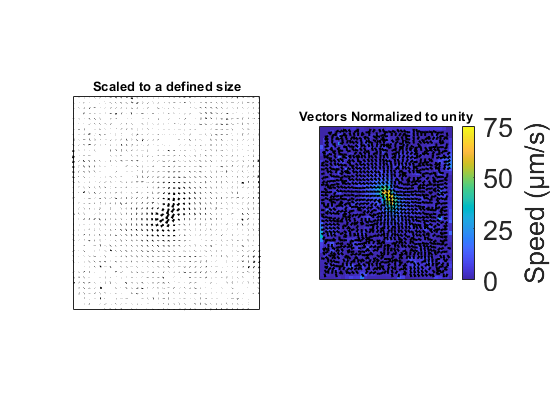

% Note that I replaced the scale to 0.8 (1/0.8 = 1.25 see funciton for more details) to avoid vectors walking on each
% other using the quiver function. It does not matter, as all vectors here
% are normalized.
title('Vectors Normalized to unity')
axis tight
set(gca,'xtick',[],'ytick',[]);
caxis([0 75])
cb = ColorBarSet('Speed (µm/s)',[0 25 50 75], 'FontSize', 20);

% savefig(gcf, '2DFlow_AveragedZ.fig')
% exportgraphics(gcf,'2DFlow_AveragedZ.png', 'ContentType', 'image', 'Resolution', 600) 

## Performing the rotation and centering for the maximal velocity around the center

% calculate the rotated tracks
[TracksRotated, Tetha1, Center1] = RotateTracksMaxVelocity2D(x, y, U2D, V2D, Tracks, Settings);
[~, ~, U2DRT, V2DRT, ~] = Flow2D(x, y, TracksRotated, ThresholdCounts);
% iterate for better alignment. This is needed due to the finite mesh
[TracksRotated, Tetha2, Center2] = RotateTracksMaxVelocity2D(x, y, U2DRT, V2DRT, TracksRotated, Settings);
[X2D, Y2D, U2DRT, V2DRT, Velocity2DRT] = Flow2D(x, y, TracksRotated, ThresholdCounts);
MaxAverageVelocity = max(max(Velocity2DRT))

MaxAverageVelocity = 81.0306

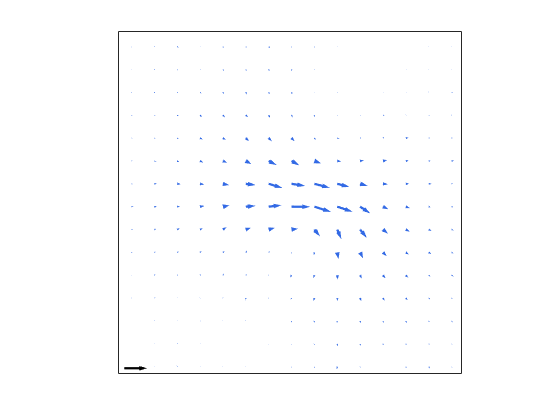

figure;
for P1 = 1:size(Y2D,1) 
    for P2 = 1:size(Y2D,2)
        if ~isnan(Velocity2DRT(P1,P2))
            Origin = [X2D(P1,P2) Y2D(P1,P2) 0];
            Target = Origin + [U2DRT(P1,P2) V2DRT(P1,P2) 0]*Delta/ScaleVelocity2D;
            mArrow3(Origin,Target,'color',ColorArrow,'stemWidth',0.20,'tipWidth',0.40);
            hold on
        end
    end
end
axis equal
% Reference arrow is plotted here
OriginScale = [46 51 0];
Target = OriginScale + [Delta 0 0];
mArrow3(OriginScale, Target,'color',[0 0 0],'stemWidth',0.2,'tipWidth',0.40);
set(gca,'XTick',[],'YTick',[])
axis equal
xlim([45 105])
ylim([50 110])
box on

## 3D Flow profile

Rotating the 3D flow

Making 3D quiver plot on a thin layer around the center

[X3D, Y3D, Z3D, U3DRT, V3DRT, W3DRT, Velocity3D] = Flow3D(x, y, z, TracksRotated, ThresholdCounts);
MaxAverageVelocity = max(max(max(Velocity3D)))

MaxAverageVelocity = 140.5015

ScaleVelocity3D = 125;

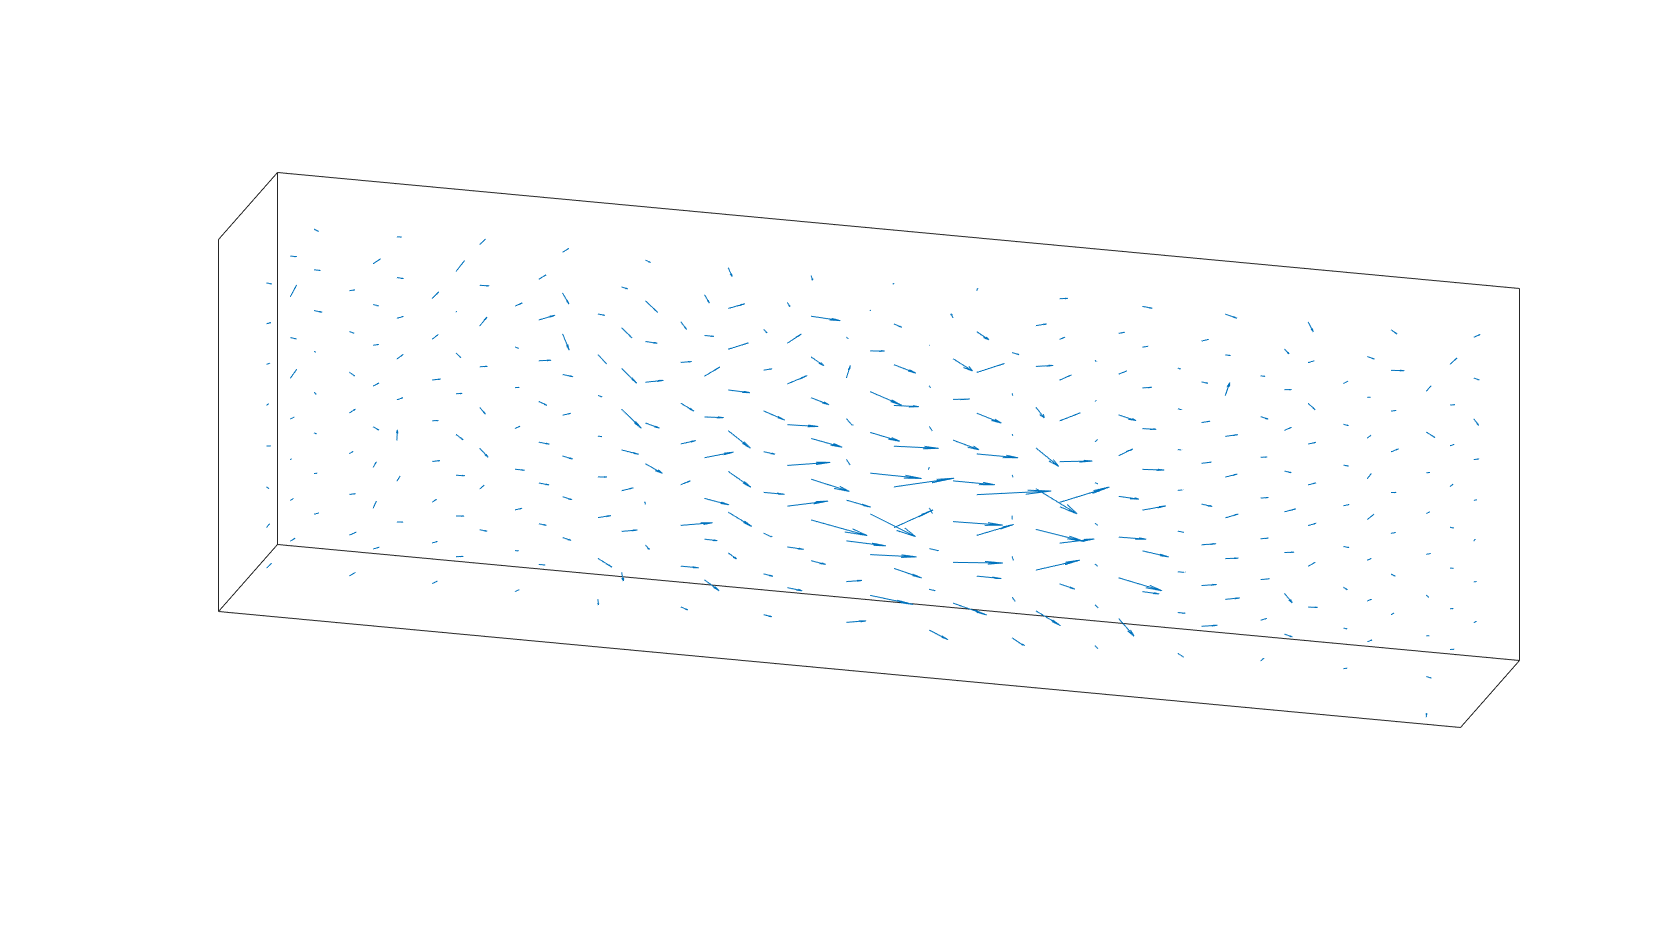

% Quiver showing the central part
figure
quiver3(X3D,Y3D,Z3D,U3DRT,V3DRT,W3DRT);
hold on
axis equal
axis tight
view (16,19)
xlim([45 105])
ylim([75 85])
box on
set(gca,'ZDir','reverse');
set(gca,'XTick',[],'YTick',[],'ZTick',[])
set(gcf,'Visible','on')
set(gcf,'WindowState','maximized')

% savefig(gcf, '3DFlow_ThinSection.fig')
% exportgraphics(gcf,'3DFlow_ThinSection.png', 'ContentType', 'image', 'Resolution', 600) 

## Evaluating distance between cells for arrow normalization

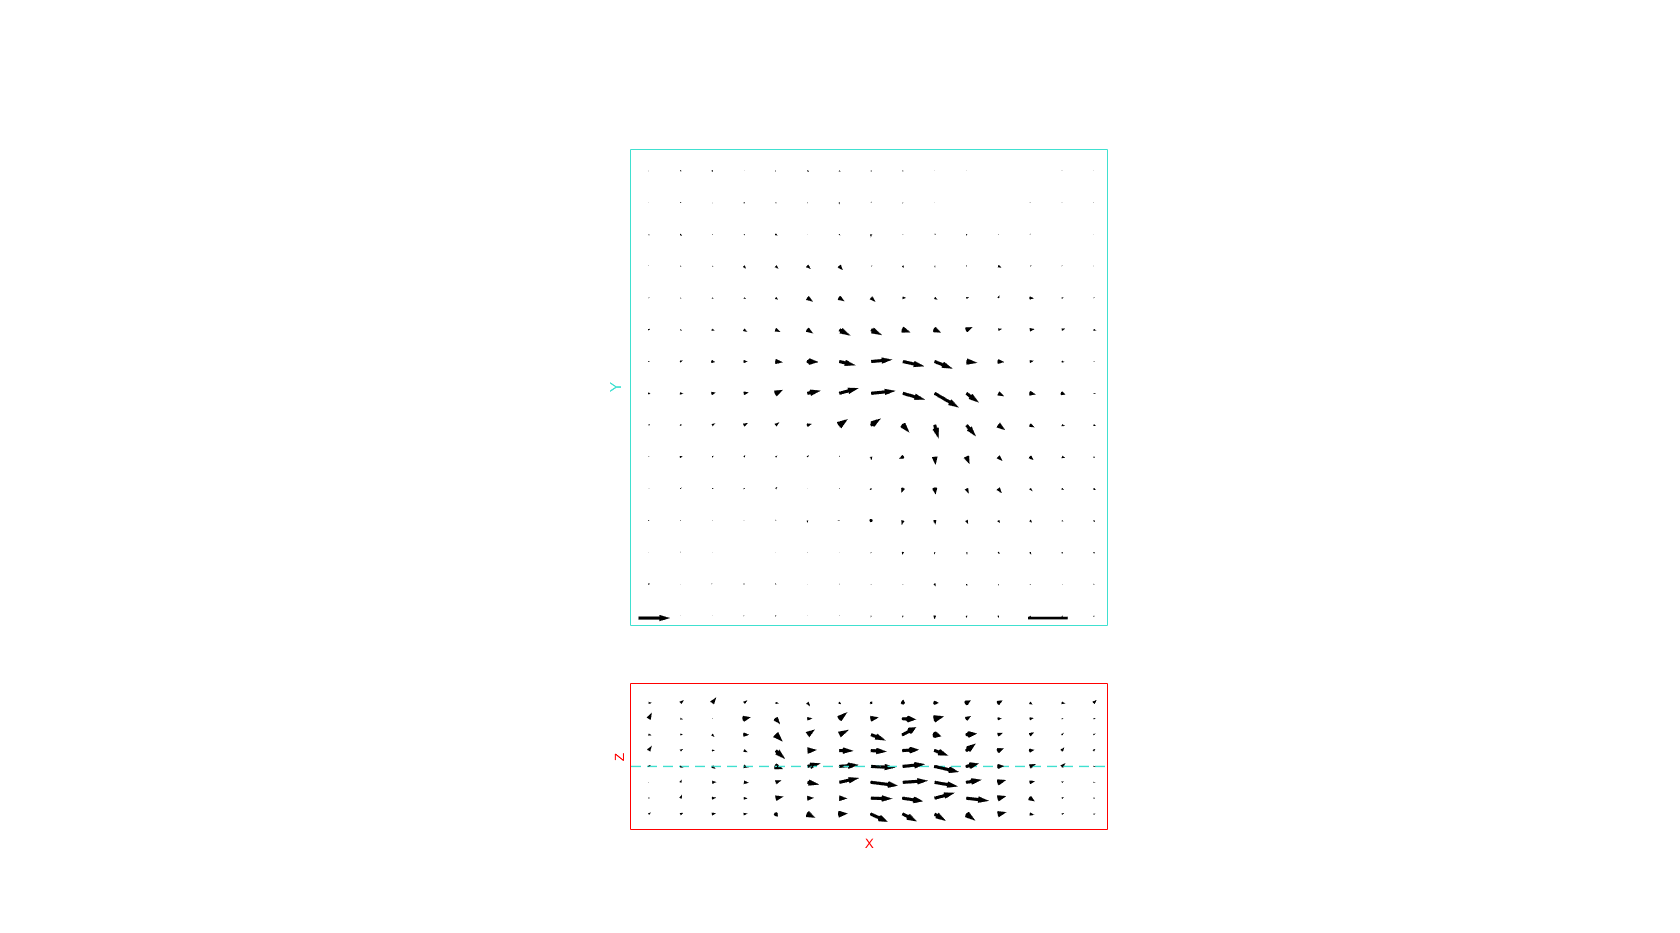

figure
subplot(4,1,4)
ColorArrow = [0 0 0];
plot3([45 105],y(20)*[1 1],z(5)*[1 1],'--', 'LineWidth',1,'Color',[64 224 208]/255)
hold on
for P1 = 20
    for P2 = 1:size(Z3D,2)
        for P3 = 1:size(Z3D,3)
            if ~isnan(U3DRT(P1,P2,P3))
                Origin = [X3D(P1,P2,P3) Y3D(P1,P2,P3) Z3D(P1,P2,P3)];
                Target = Origin + [U3DRT(P1,P2,P3) V3DRT(P1,P2,P3) W3DRT(P1,P2,P3)]*Delta/ScaleVelocity3D;
                mArrow3(Origin,Target,'color',ColorArrow,'stemWidth',0.2,'tipWidth',0.4);
            end
        end
    end
end
hold on
axis equal
axis tight
zlim([15 LocationGlass])
xlim([45 105])
view(0, 0) 
box on
set(gca,'ZDir','reverse');
set(gca,'XTick',[],'YTick',[],'ZTick',[])
zlabel('Z')
xlabel('X')
Axis1 = gca;
Axis1.XColor = 'red';
Axis1.ZColor = 'red';

subplot(4,1,[1 3])
ColorArrow = [0 0 0]; %[64 224 208]/255;
%% Evaluating distance between cells for arrow normalization
for P1 = 1:size(Z3D,1)
    for P2 = 1:size(Z3D,2)
        for P3 = 5
            if ~isnan(U3DRT(P1,P2,P3))
                Origin = [X3D(P1,P2,P3) Y3D(P1,P2,P3) Z3D(P1,P2,P3)];
                Target = Origin + [U3DRT(P1,P2,P3) V3DRT(P1,P2,P3) W3DRT(P1,P2,P3)]*Delta/ScaleVelocity3D;
                mArrow3(Origin,Target,'color',ColorArrow,'stemWidth',0.2,'tipWidth',0.4);
            end
        end
    end
end
% Plot scale arrow velocity
OriginScale = [46 51 0];
Target = OriginScale + [Delta 0 0];
mArrow3(OriginScale,Target,'color','k','stemWidth',0.2,'tipWidth',0.4);
axis equal
axis tight
ylim([50 110])
xlim([45 105])
box on
Axis2 = gca;
set(Axis2,'ZDir','reverse');
set(Axis2,'XTick',[],'YTick',[],'ZTick',[])
Axis2.XColor = [64 224 208]/255;
Axis2.YColor = [64 224 208]/255;
% Scale space
hold on
OriginScale = [95 51 0];
plot3([95 (95+5)], [51 51],[0 0],'LineWidth',2,"Color",'k');
ylabel('Y')
% Adjusting 
Pos1 = get(Axis1, 'Position');  
Pos2 = get(Axis2, 'Position');                  
set(Axis2, 'Position', [Pos2(1:3)  Pos1(4)*(110-50)/(LocationGlass - 15)])  
set(gcf,'Visible','on')
set(gcf,'WindowState','maximized')
savefig(gcf, 'SectionsZ10µm_YCenteredArrowFlow.fig')
exportgraphics(gcf,'SectionsZ10µm_YCenteredArrowFlow.png', 'ContentType', 'image', 'Resolution', 300) 

## Calculating now the center of the rotation, the velocity direction, and the surrounding square in the original track orientation

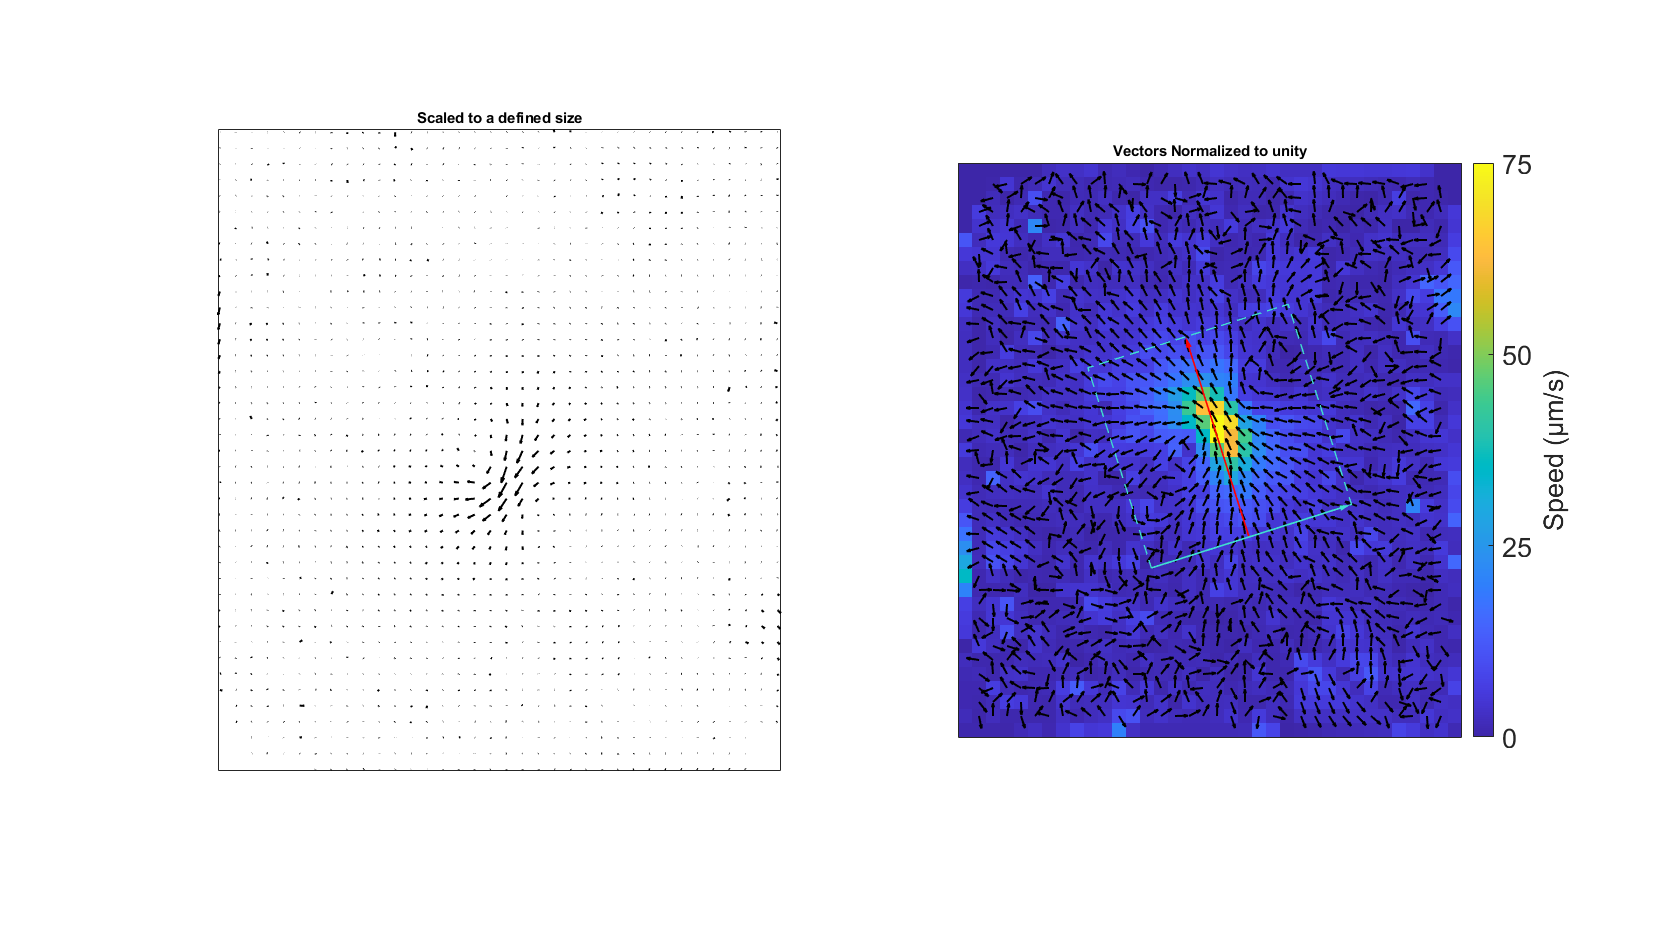

Range_y = [50 110]; % Range is used for plotting
Range_x= [45 105];
%Range_z = [15 LocationGlass];
% The corresponding corners are
Point1 = [45 50];
Point2 = [45 110];
Point3 = [105 110];
Point4 = [105 50];
% Transforming back
Point1_Back = TraceBackPoint(Point1, Tetha1, Tetha2, Center1, Center2);
Point2_Back = TraceBackPoint(Point2, Tetha1, Tetha2, Center1, Center2);
Point3_Back = TraceBackPoint(Point3, Tetha1, Tetha2, Center1, Center2);
Point4_Back = TraceBackPoint(Point4, Tetha1, Tetha2, Center1, Center2);
% Adding rectangle to the figure
figure(GeneralFig)
subplot(1,2,2) 
hold on
x_Rectangle = [Point1_Back(1), Point2_Back(1), Point3_Back(1), Point4_Back(1) Point1_Back(1)];
y_Rectangle = [Point1_Back(2), Point2_Back(2), Point3_Back(2), Point4_Back(2) Point1_Back(2)];
plot(x_Rectangle, y_Rectangle, '--', 'Color', [64 224 208]/255, 'LineWidth', 1);
mArrow3([Point1_Back 0],[Point2_Back 0],'color', [64 224 208]/255,'stemWidth',0.4,'tipWidth',1);
% Adding the red line in the center of the transformation
Transformation_Vector = Center2 + [1 0]; % Remeber flow was aligned in this direction
Transformation_Vector_Back = TraceBackPoint(Transformation_Vector, Tetha1, Tetha2, Center1, Center2);
Center_Max_Flow = TraceBackPoint(Center2, Tetha1, Tetha2, Center1, Center2);
LengthLine = Range_x(2) - Range_x(1);
InitLine = Center_Max_Flow - 0.5*(Transformation_Vector_Back - Center_Max_Flow)*LengthLine;
EndLine =  Center_Max_Flow + 0.5*(Transformation_Vector_Back - Center_Max_Flow)*LengthLine;
mArrow3([InitLine 0],[EndLine 0],'color','r','stemWidth',0.4,'tipWidth',1);
% plot([InitLine(1) EndLine(1)], [InitLine(2) EndLine(2)], '--r', 'LineWidth', 1)
set(gca,'ZDir','reverse');
set(GeneralFig,'Visible','on')
set(GeneralFig,'WindowState','maximized')
% savefig(GeneralFig, 'Rotated_2DFlow_AveragedZ.fig')
exportgraphics(GeneralFig,'Rotated_2DFlow_AveragedZ.png', 'ContentType', 'image', 'Resolution', 300) 

function PlotStandardQuiver2D(X,Y,U,V,ScaleVelocity, ShowScale)
    if nargin == 5
        ShowScale = true;
    end
    Velocity = sqrt(U.*U + V.*V);
    MaxAverageVelocity = max(max(Velocity))
    q = quiver(X,Y,U,V,MaxAverageVelocity/ScaleVelocity);
    q.LineWidth = 1.5;
    q.MaxHeadSize = 0.2;
    q.Color = [0 0 0];
    hold on
    
    % Displaying scale arrow
    if ShowScale
        P  = zeros(size(U));
        P(end,end-1) = 1;
        q2 = quiver(X,Y,P,zeros(size(V)),1);
        q2.LineWidth = 1.5;
        q2.Color = [0 0.5 0.75];
        q2.MaxHeadSize = 0.2;
        text(X(end,end-1),Y(end,end-1)+10,strcat(num2str(ScaleVelocity),' µm/s'),'FontSize',14)
    end
    axis equal
return
end

function [X2D, Y2D, U2D, V2D, Velocity2D] = Flow2D(x, y, Tracks, ThresholdCounts)
    % x and y are the mesh points where the velocity is calculated
    %% Calculating the 2D components of the flow
    TotalNumberTracks = length(Tracks);
    [X2D,Y2D] = meshgrid(x,y);
    U2D = 0*X2D; % Velocity Mesh innitialization
    V2D = 0*Y2D; % Velocity Mesh innitialization
    CU = 0*X2D; %accumulating here contributors for each mesh point to later calculating the mean
    for ID = 1:TotalNumberTracks
        CurrentTrack = Tracks(ID).Track';
        TrackVelocity = Tracks(ID).Velocity;
        [NoNaNFrames, ~] = NoNaN(TrackVelocity(:,1));
        for CurrentFrame = NoNaNFrames
            R = CurrentTrack(CurrentFrame,:);  
            %Localizing the nearest point in the 2D mesh for averaging
            [~,I] = min(abs(X2D(1,:) - R(1)),[],'omitnan');
            [~,J] = min(abs(Y2D(:,I) - R(2)),[],'omitnan');        
            % Accumulating velocity on the velocity mesh
            U2D(J,I) = U2D(J,I) + TrackVelocity(CurrentFrame,1);
            V2D(J,I) = V2D(J,I) + TrackVelocity(CurrentFrame,2);       
            % Anotating the number of elements contributing to that mesh calcualtion for later to obtaining the mean
            CU(J,I) = CU(J,I) + 1;
        end
    end
    CU(CU<ThresholdCounts) = NaN; %Suppressing form the output those points that have a low number of particles to give a proper average
    % calculating the average
    U2D = U2D./CU;
    V2D = V2D./CU;
    % Interpolating missing data
    POI = ~isnan(U2D); %Point os interest for interpolation
    U2D = griddata(X2D(POI),Y2D(POI),U2D(POI),X2D,Y2D);
    V2D = griddata(X2D(POI),Y2D(POI),V2D(POI),X2D,Y2D);
    Velocity2D = sqrt(U2D.*U2D + V2D.*V2D);
    return
end

function [X3D, Y3D, Z3D, U3D, V3D, W3D, Velocity3D] = Flow3D(x, y, z, Tracks, ThresholdCounts)
    TotalNumberTracks = length(Tracks);
    [X3D, Y3D, Z3D] = meshgrid(x,y,z);
    U3D = 0*X3D; % Velocity Mesh
    V3D = 0*Y3D;
    W3D = 0*Z3D;
    CU = 0*X3D; %Contributors in the mesh
    for ID = 1:TotalNumberTracks
        CurrentTrack = Tracks(ID).Track';
        TrackVelocity = Tracks(ID).Velocity;
        [NoNaNFrames, ~] = NoNaN(TrackVelocity(:,1));
        for CurrentFrame = NoNaNFrames
            R = CurrentTrack(CurrentFrame,:);
            % locating the nearest coordinates in the mesh where each point in the
            % track belongs
            [~,I] = min(abs(X3D(1,:,1) - R(1)),[],'omitnan');
            [~,J] = min(abs(Y3D(:,I,1) - R(2)),[],'omitnan');
            [~,K] = min(abs(Z3D(J,I,:) - R(3)),[],'omitnan');
            %% Accumulating velocity on the velocity mesh
            U3D(J,I,K) = U3D(J,I,K) + TrackVelocity(CurrentFrame,1);
            V3D(J,I,K) = V3D(J,I,K) + TrackVelocity(CurrentFrame,2);
            W3D(J,I,K) = W3D(J,I,K) + TrackVelocity(CurrentFrame,3);       
            %% Anotating the number of elements contributing to that mesh calcualtion for later to obtaining the average
            CU(J,I,K) = CU(J,I,K) + 1;   
        end
    end
    % calculating the average
    CU(CU<ThresholdCounts) = NaN;
    U3D = U3D./CU;
    V3D = V3D./CU;
    W3D = W3D./CU;
    POI = ~isnan(U3D); %Point of interest for interpolation
    U3D = griddata(X3D(POI),Y3D(POI),Z3D(POI),U3D(POI),X3D,Y3D,Z3D);
    V3D = griddata(X3D(POI),Y3D(POI),Z3D(POI),V3D(POI),X3D,Y3D,Z3D);
    W3D = griddata(X3D(POI),Y3D(POI),Z3D(POI),W3D(POI),X3D,Y3D,Z3D);
    Velocity3D = sqrt(U3D.*U3D + V3D.*V3D + W3D.*W3D);
    return
end

function [TracksRotated, Theta, Center] = RotateTracksMaxVelocity2D(x, y, U2D, V2D, Tracks, Settings)
    % I look now for the maximal velocity. Where it is located, and in which direction
    TotalNumberTracks = length(Tracks);
    Velocity2D = sqrt(U2D.*U2D + V2D.*V2D);
    [M,I] = max(Velocity2D,[],"omitnan");
    [~,J] = max(M,[],"omitnan");
    Center = [x(J) y(I(J))];
    % now rotating to make the velocity vector lay in the x positive axis
    Theta = cart2pol(U2D(I(J),J),V2D(I(J),J)); %Orientation angle of the maximal velocity vector
    
    TracksRotated = Tracks; %Now lets translate and rotate all tracks (center at largest velocity vector and this lays on the postive x axis)
    for ID = 1:TotalNumberTracks
        CurrentTrack = Tracks(ID).Track';
        % translating
        CurrentTrack(:,1) = CurrentTrack(:,1) - x(J);
        CurrentTrack(:,2) = CurrentTrack(:,2) - y(I(J));
        % Rotating
        [T,R] = cart2pol(CurrentTrack(:,1),CurrentTrack(:,2));
        [CurrentTrack(:,1),CurrentTrack(:,2)] = pol2cart(T - Theta,R); 
        % Translating back
        CurrentTrack(:,1) = CurrentTrack(:,1) + x(J);
        CurrentTrack(:,2) = CurrentTrack(:,2) + y(I(J));
        TracksRotated(ID).Track = CurrentTrack';    
        [~, VelX] = CalculateDerivative(CurrentTrack(:,1));
        [~, VelY] = CalculateDerivative(CurrentTrack(:,2));
        [~, VelZ] = CalculateDerivative(CurrentTrack(:,3));
        TracksRotated(ID).Velocity = [VelX VelY VelZ]*Settings.AcquisitionRate*Settings.PixelSize; % µm/s
    end
return
end

function OriginalCoordinates = TraceBackPoint(Point, Tetha1, Tetha2, Center1, Center2)
    % Tracing back second transformation
    PointIntermediate = Point - Center2;
    [TethaIntermediate, RhoIntermediate] = cart2pol(PointIntermediate(1), PointIntermediate(2));
    TethaIntermediate = TethaIntermediate + Tetha2;
    [PointIntermediate(1), PointIntermediate(2)] = pol2cart(TethaIntermediate, RhoIntermediate);
    PointIntermediate = PointIntermediate + Center2;
    % Tracing back first transformation
    PointIntermediate = PointIntermediate - Center1;
    [TethaIntermediate, RhoIntermediate] = cart2pol(PointIntermediate(1), PointIntermediate(2));
    TethaIntermediate = TethaIntermediate + Tetha1;
    [PointIntermediate(1), PointIntermediate(2)] = pol2cart(TethaIntermediate, RhoIntermediate);
    OriginalCoordinates = PointIntermediate + Center1;  
end